## Demo of Matlab functions 

Used in this demo: zeros, for, reshape, prctile, sum, plotyy, scatter

## First some basics on matrix algebra

scalar multiplication and division

x = [1 2 3; 4 5 6]

x =      1     2     3
     4     5     6


3*x

ans =      3     6     9
    12    15    18


3*x/2

ans =     1.5000    3.0000    4.5000
    6.0000    7.5000    9.0000


matrix addition and subtraction

x = [1 2;3 4;5 6]

x =      1     2
     3     4
     5     6


y = [6 5;4 3;2 1]

y =      6     5
     4     3
     2     1


x+y

ans =      7     7
     7     7
     7     7


x-y

ans =     -5    -3
    -1     1
     3     5


matrix multiplication

(3-by-2) * (2-by-3) = (3-by-3)

x*y'

ans =     16    10     4
    38    24    10
    60    38    16


(2-by-3) * (3-by-2) = (2-by-2)

x'*y

ans =     28    19
    40    28


##    Code to help with Assignment 1

clear
close all
load SIO_TEMP_1917_2025.mat
whos

  Name            Size             Bytes  Class       Attributes

  T           39751x1             318008  double                
  readme          1x70               140  char                  
  time        39751x1             318008  datetime              



## A for loop repeats statements between "for" and "end".  At each iteration, the for loop index (j) increases.

for j = 1:10
    out(j) = j*2;
end

out

out =      2     4     6     8    10    12    14    16    18    20


## **Form a 2-dimensional array of T summer day vs year using a for loop   **

[yr,mo,dy] = datevec(time);  %Get the month, day, and year for each point
nyr = yr(end)-yr(1)+1;       %number of years
nday = 31 + 31 + 30;         %number of days July-September

When filling a large output array, create the  array first and then fill.  In this case, Tsummer starts as a nday x nyr array of all zeros

Tsummer = zeros(nday,nyr);

Fill Tsummer using a for loop.  The columns correpond to years.

for j = 1:nyr
    Tsummer(:,j) = T(mo>=7 & mo <=9 & yr == 1916+j);
end

Plot all years vs day of summer starting with July 1.

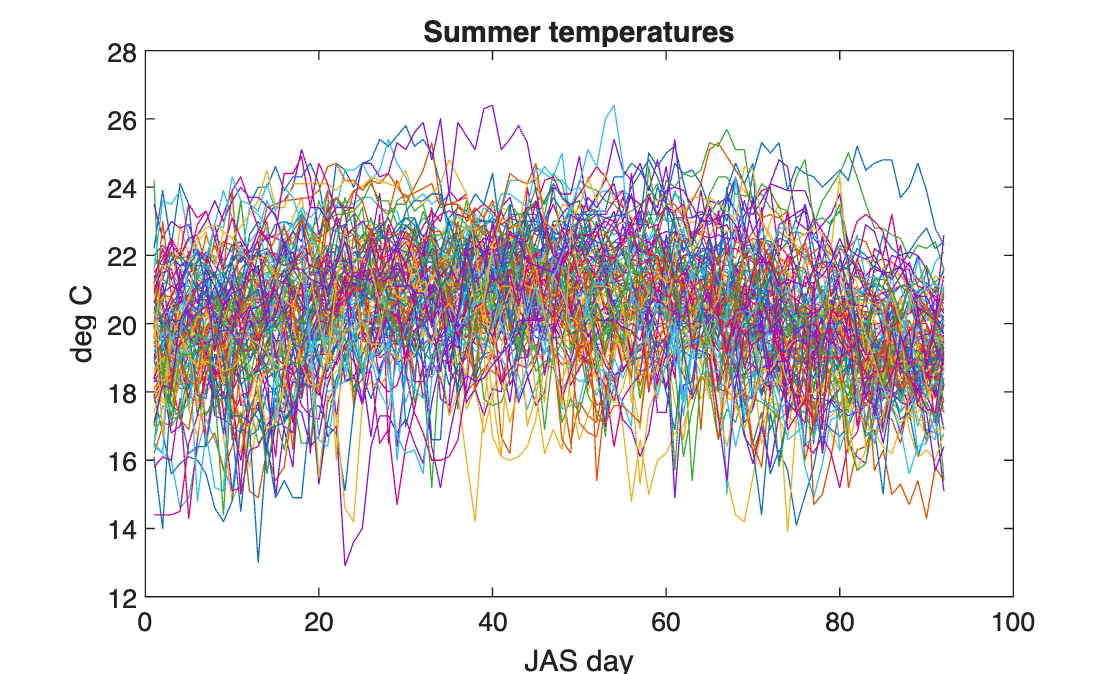

figure (1)
clf
plot(1:nday,Tsummer)
xlabel('JAS day')
ylabel('deg C')
title('Summer temperatures')

Plot Summer Temperature (deg F) all years vs day of summer starting with July 1.

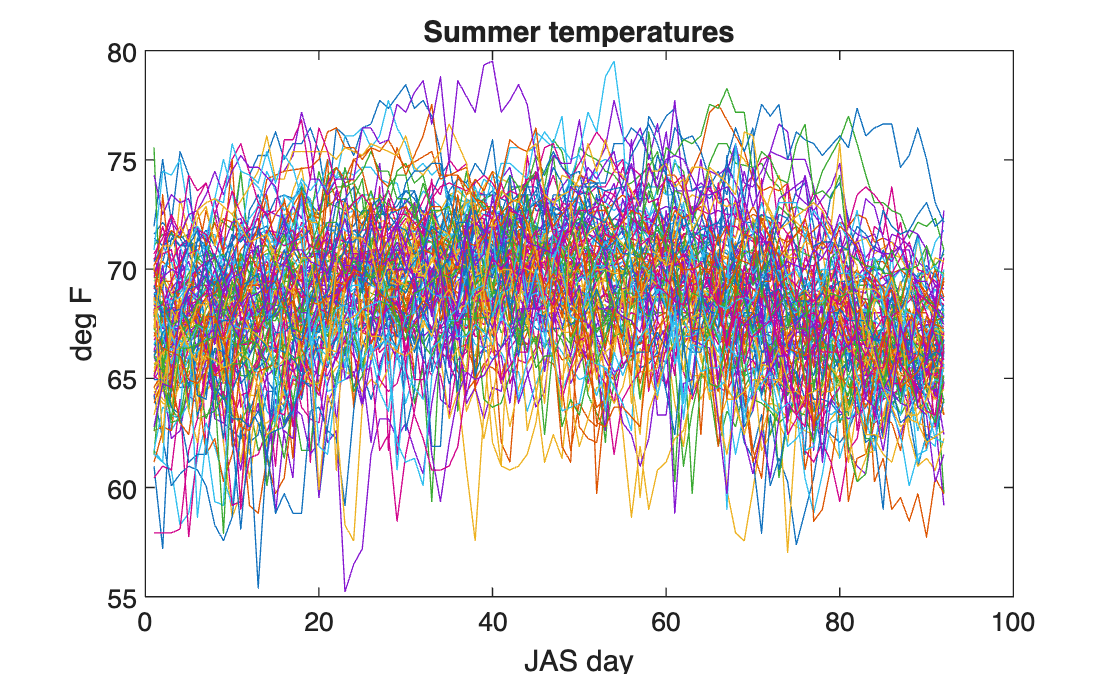

figure (12)
clf
plot(1:nday,Tsummer*9/5+32)
xlabel('JAS day')
ylabel('deg F')
title('Summer temperatures')

Plot the mean (over all years) for each summer day 

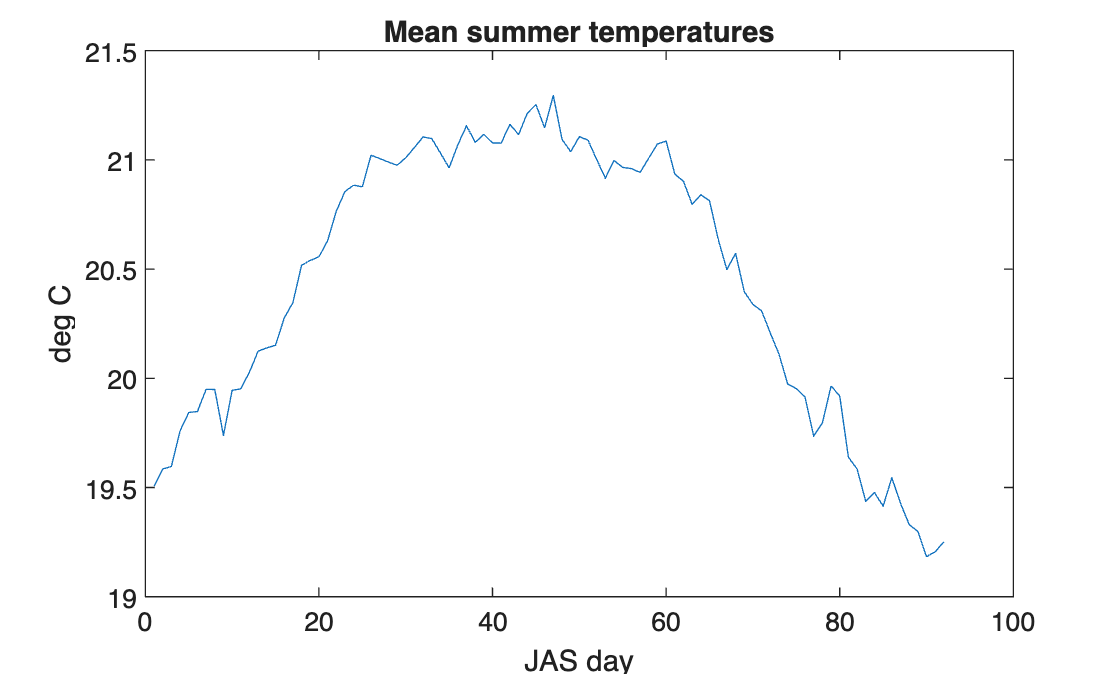

figure (2)
clf
plot(1:nday,mean(Tsummer,2))
xlabel('JAS day')
ylabel('deg C')
title('Mean summer temperatures')

Plot the mean (over all summer days) for each year

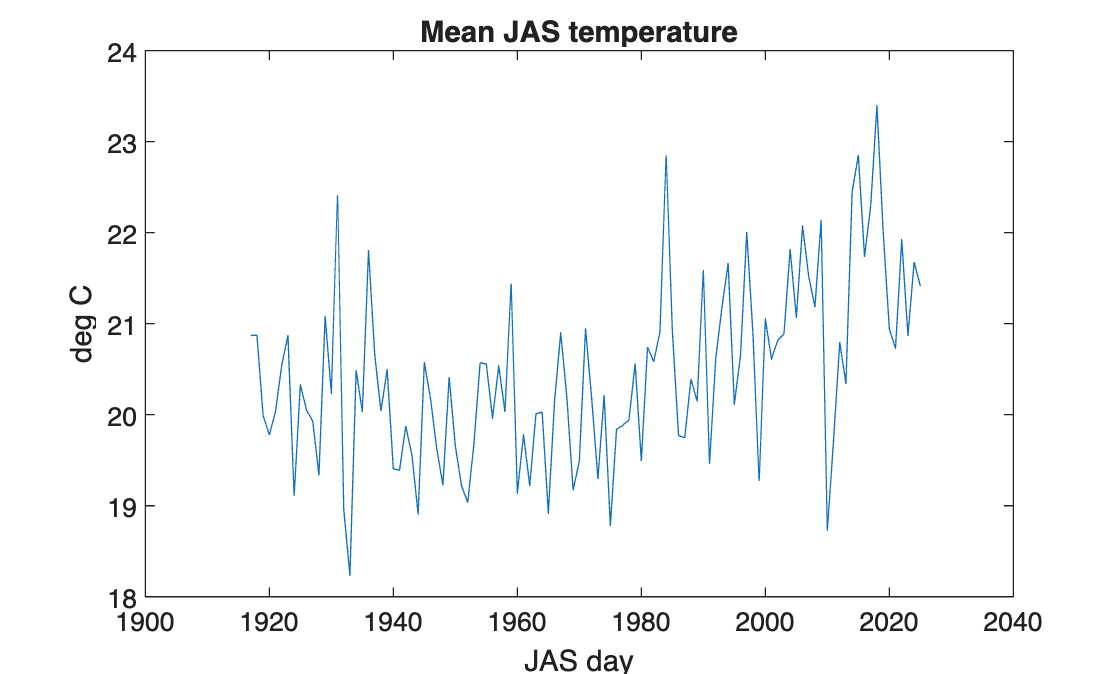

figure (3)
clf
plot(yr(1):yr(end),mean(Tsummer))
xlabel('JAS day')
ylabel('deg C')
title('Mean JAS temperature')

Plot the 10th and 90th percentile (over all years) for each summer day

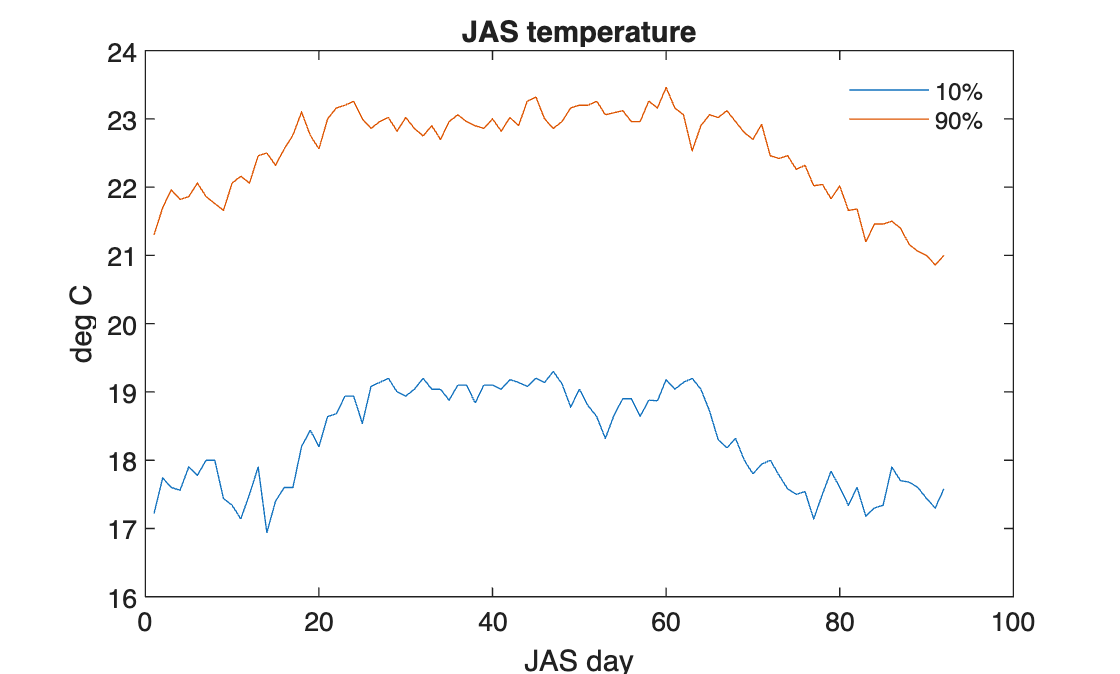

figure (4)
clf
plot(1:nday,prctile(Tsummer,[10 90],2))
xlabel('JAS day')
ylabel('deg C')
title('JAS temperature')
legend('10%','90%')
legend('boxoff')

## **Reshape reorganizes the array elements**

**reshape(x,m,n) returns a m-by-n matrix whose elements are taken columnwise from x.  x must have m*n elements.**

x = 1:12

x =      1     2     3     4     5     6     7     8     9    10    11    12


reshape(x,3,4)

ans =      1     4     7    10
     2     5     8    11
     3     6     9    12


reshape(x,6,2)

ans =      1     7
     2     8
     3     9
     4    10
     5    11
     6    12


## **Form a 2-dimensional array of T summer day vs year using reshape**

Tsummer2 = reshape(T(mo>=7 & mo <=9),nday,nyr);

Confirm that Tsummer2 (reshape) is identical to Tsummer (for loop)

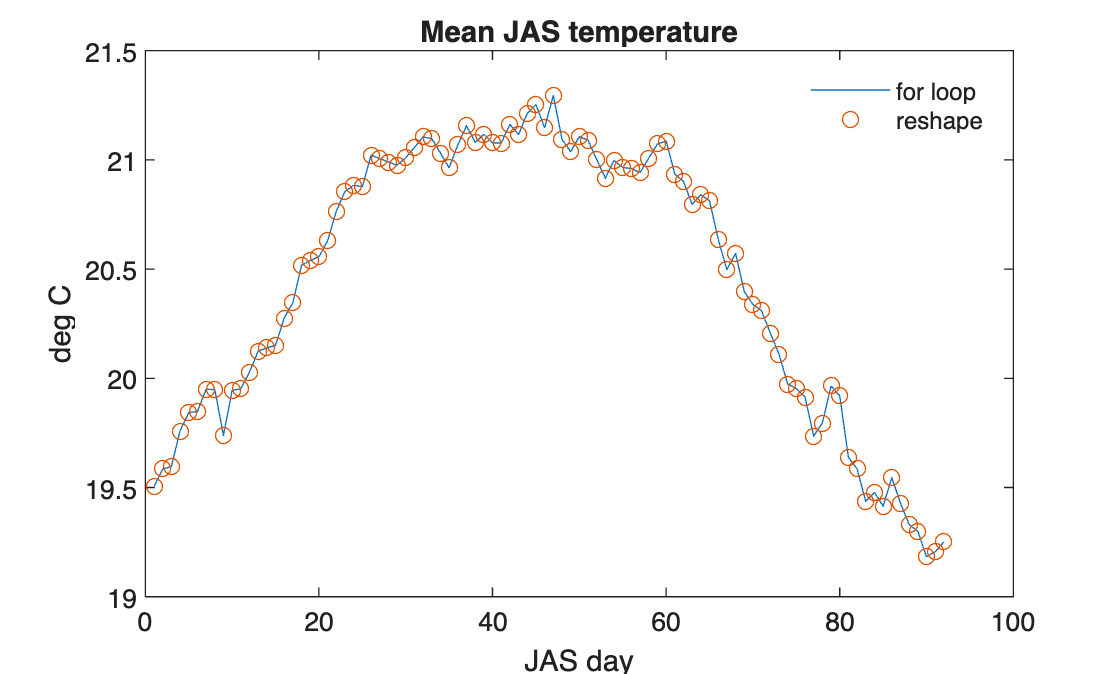

figure (5)
clf
plot(1:nday,mean(Tsummer,2),1:nday,mean(Tsummer2,2),'o')
legend('for loop','reshape')
legend('boxoff')
xlabel('JAS day')
ylabel('deg C')
title('Mean JAS temperature')

Use either for loop or reshape for summer temperature analysis

## Code to compute number of days above 95th percentile temperature 

Using a for loop

for j = 1:nyr
    heat_days(j) = sum(Tsummer(:,j) > prctile(Tsummer,95,2));
end

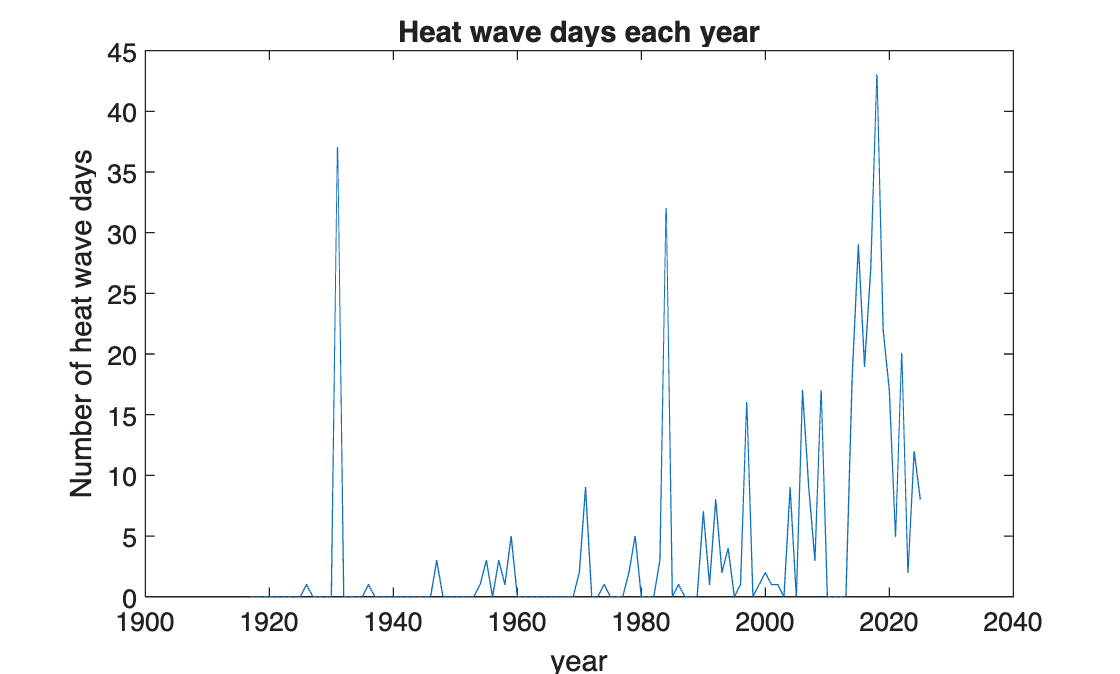

figure (6)
clf
plot(yr(1):yr(end),heat_days)
xlabel('year')
ylabel('Number of heat wave days')
title('Heat wave days each year')

Using repmat

x = (1:2)'

x =      1
     2


repmat(x,1,2)

ans =      1     1
     2     2


repmat(x,2,1)

ans =      1
     2
     1
     2


repmat(x,2,2)

ans =      1     1
     2     2
     1     1
     2     2


Confirm that heat_day2 (repmat) is identical to heat_days (for loop)

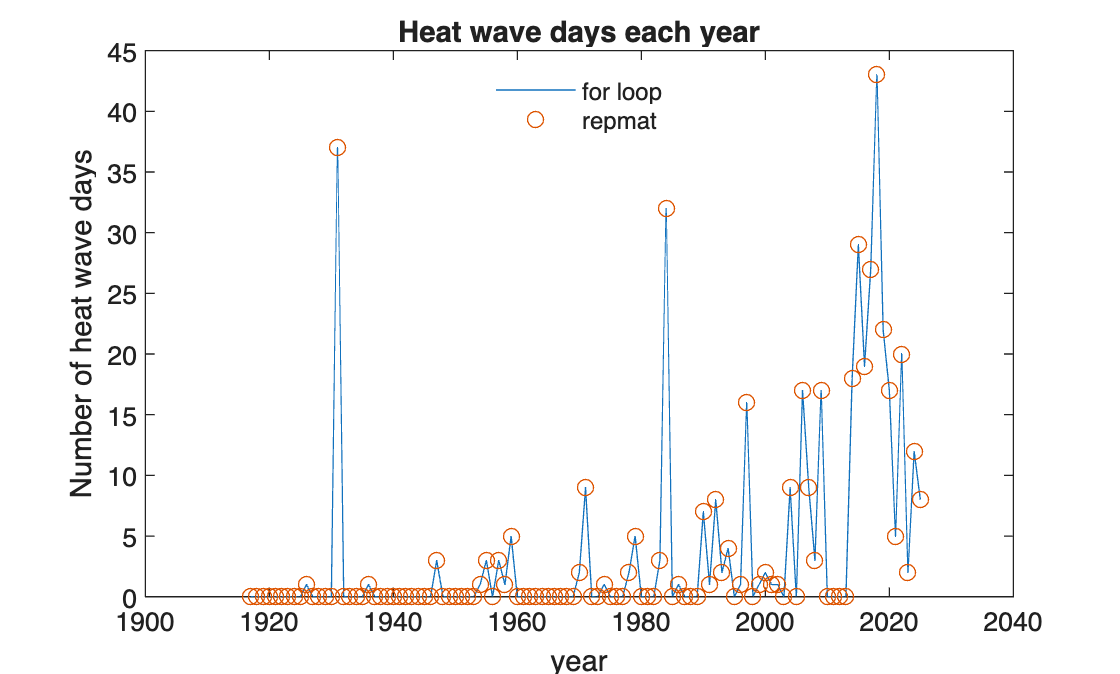

heat_days2 = sum(Tsummer > repmat(prctile(Tsummer,95,2),1,nyr));
figure (7)
clf
plot(yr(1):yr(end),heat_days,yr(1):yr(end),heat_days2,'o')
legend('for loop','repmat','Location','north')
legend('boxoff')
xlabel('year')
ylabel('Number of heat wave days')
title('Heat wave days each year')

Number of heat wave days vs JAS day

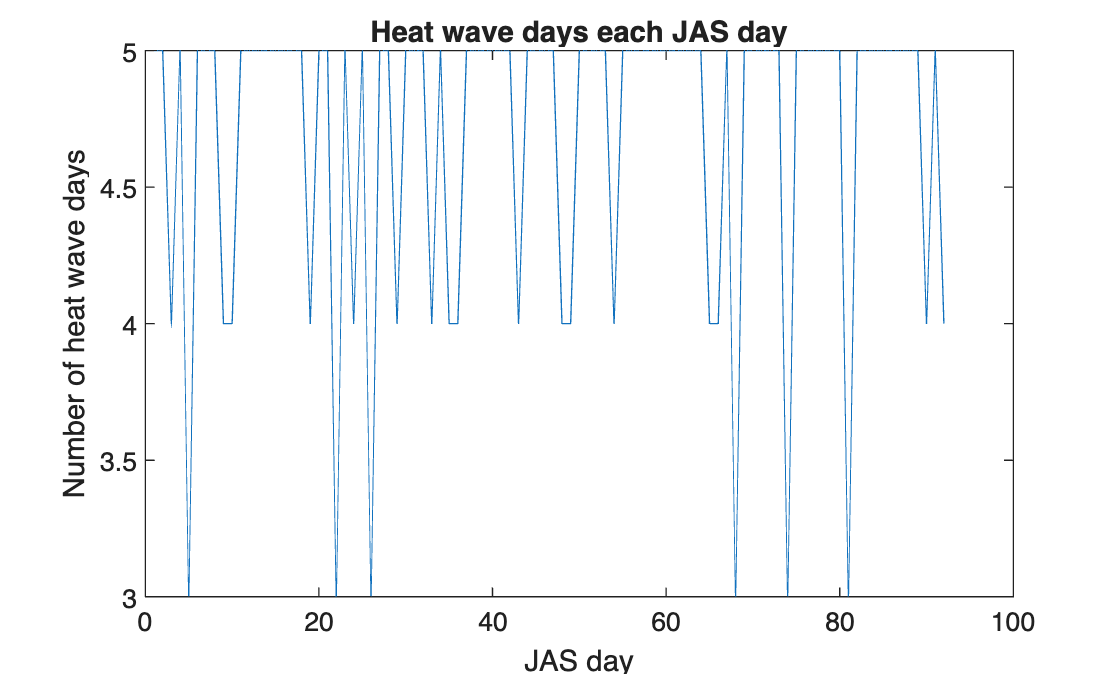

figure (8)
clf
plot(1:92,sum(Tsummer > repmat(prctile(Tsummer,95,2),1,nyr),2))
xlabel('JAS day')
ylabel('Number of heat wave days')
title('Heat wave days each JAS day')

Number of heat wave days vs JAS day over first 30 years and last 30 years

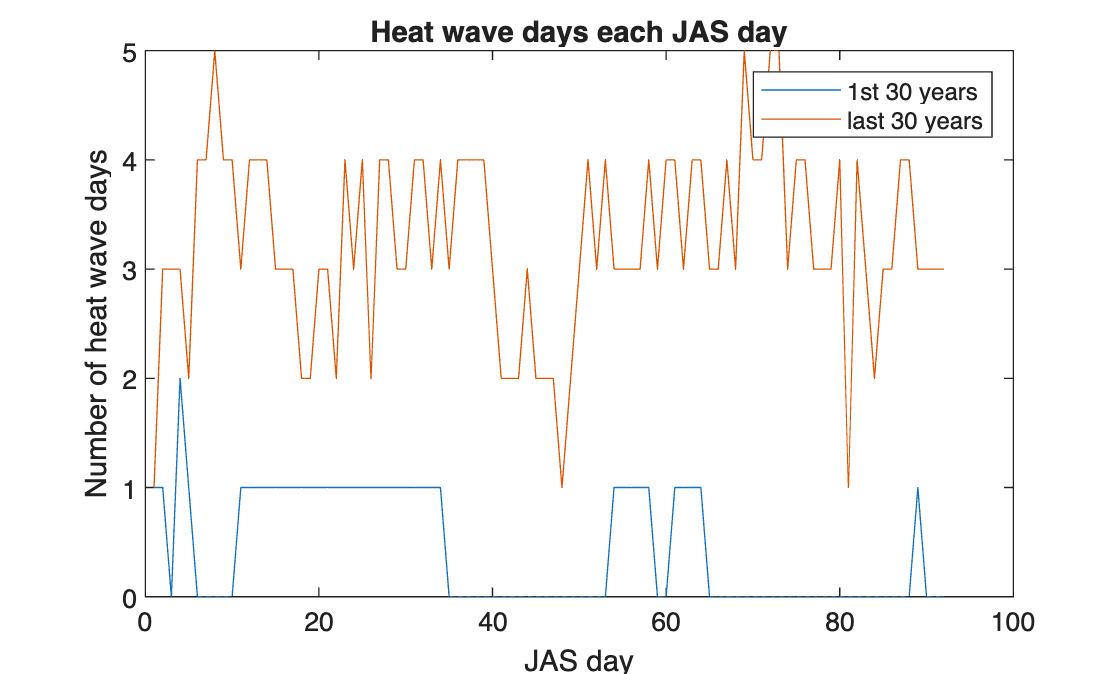

figure (9)
clf
plot(1:92,sum(Tsummer(:,1:30) > repmat(prctile(Tsummer,95,2),1,30),2))
hold on
plot(1:92,sum(Tsummer(:,end-29:end) > repmat(prctile(Tsummer,95,2),1,30),2))
legend('1st 30 years','last 30 years')
xlabel('JAS day')
ylabel('Number of heat wave days')
title('Heat wave days each JAS day')

## Plot two time series with the same x axis but different y axes on the same plot using plotyy

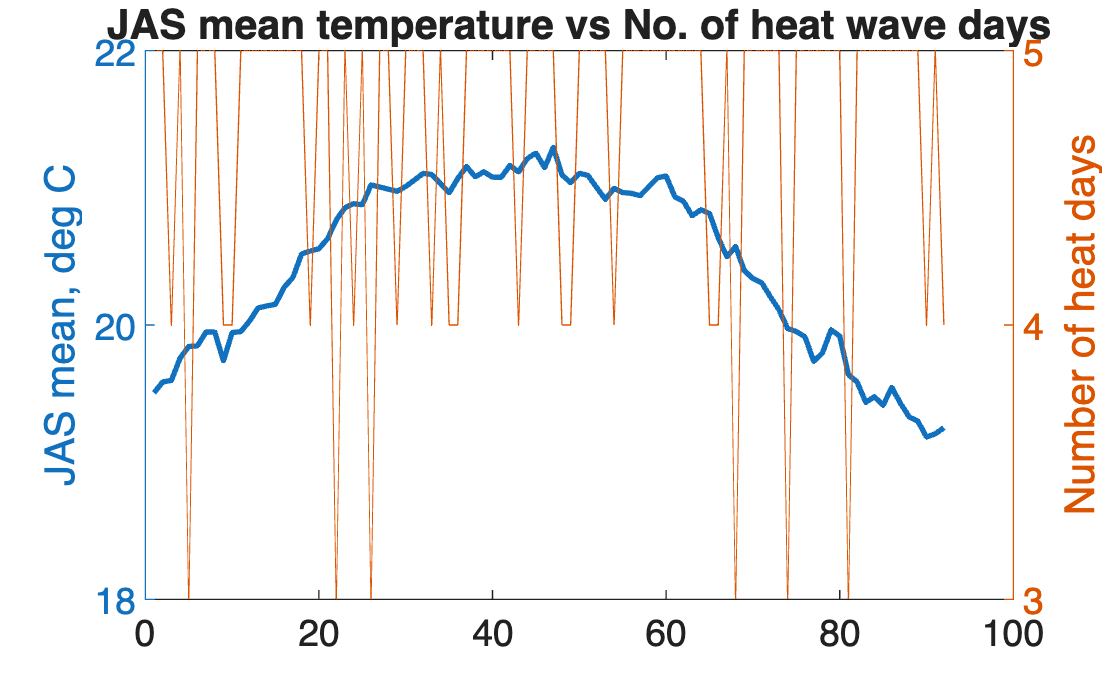

figure (10)
clf
Y1 = mean(Tsummer,2);
Y2 = sum(Tsummer > repmat(prctile(Tsummer,95,2),1,nyr),2);
[hAx,hLine1,hLine2] = plotyy(1:92,Y1,1:92,Y2);
ylabel(hAx(1),'JAS mean, deg C') % left y-axis 
ylabel(hAx(2),'Number of heat days') % right y-axis
title('JAS mean temperature vs No. of heat wave days')
set(hAx(1),'FontSize',14)
set(hAx(2),'FontSize',14)
set(hLine1,'LineWidth',2)

## Scatter plot

Compare annual average Temp vs JAS average Temp

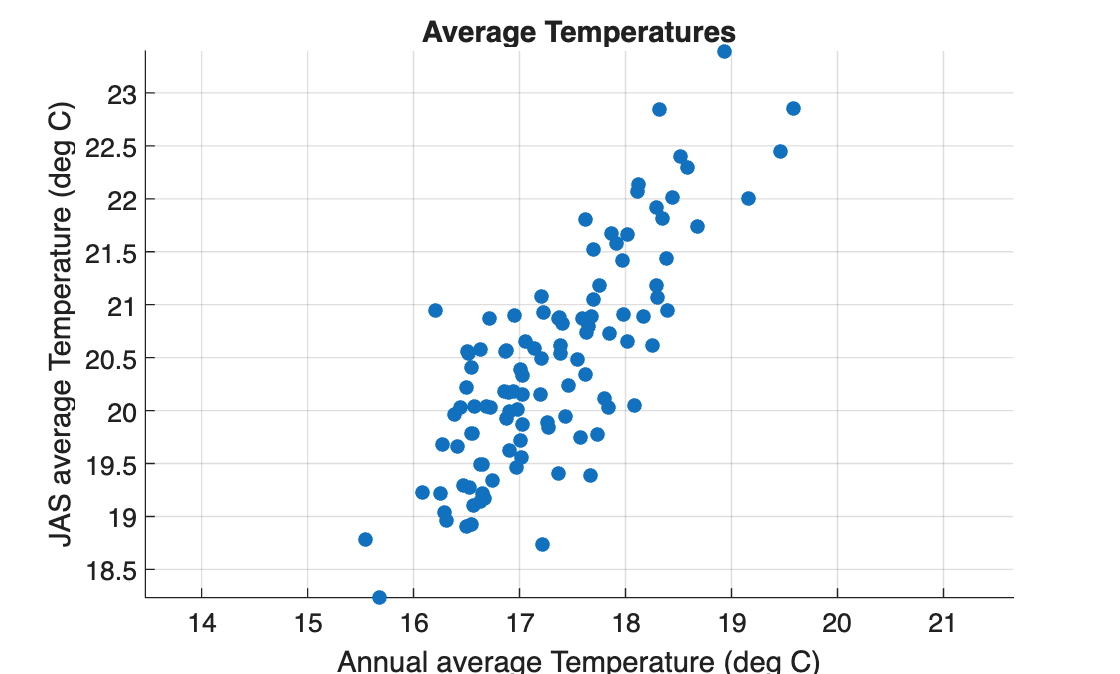

Tannual = zeros(nyr,1);
for j = 1:nyr
    Tannual(j) = mean(T(yr == 1916+j));
end
figure (11)
clf
scatter(Tannual,mean(Tsummer),30,'filled')
xlabel('Annual average Temperature (deg C)')
ylabel('JAS average Temperature (deg C)')
title('Average Temperatures')
axis('equal')

grid on